## 20250516 运放验证

%% AC Gain 数据处理

clc, clear, close all
data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[op amp] ac gain, discrete uA741, input 1 Vamp, 10 nF + 51 kOhm.txt");
V_in = data(:, 4)';
V_out = data(:, 5)';
f = data(:, 1)';
phase = - data(:, 2)';
phase = MyFilter_mean(phase, 3);

num_filt = 350;
phase(num_filt:end) = MyFilter_mean(phase(num_filt:end), 20);
V_in(num_filt:end) = MyFilter_mean(V_in(num_filt:end), 5);
V_out(num_filt:end) = MyFilter_mean(V_out(num_filt:end), 5);

A_v = (1+(1./(2*pi*f*10^(-8))+51000)/100) .* (V_out./V_in);
A_v_dB = 20*log(A_v)/log(10);

stc = MyYYPlot(f, f, A_v_dB, phase);
stc.axes.XScale = 'log';
stc.leg.String = ["Gain $A_v$ (dB)"; "Phase $\varphi\ (^\circ)$"];
stc.label.x.String = 'Frequency $f$';
stc.label.y_left.String = 'Open-Loop Small-Signal Gain $A_v$ (dB)';
stc.label.y_right.String = 'Output Phase Shift $\varphi\ (^\circ)$';
%MyFigure_ChangeSize_2048x512
ylim([0 80])
xlim([2e2, 2e5])
stc.axes.XTick = [2e2, 1e3, 2e3, 1e4, 2e4, 1e5, 2e5]

stc = 包含以下字段的 struct :
        fig: [1×1 Figure]
       axes: [1×1 Axes]
     p_left: [1×1 Line]
      label: [1×1 struct]
    p_right: [1×1 Line]
        leg: [1×1 Legend]


stc.axes.XTickLabel = ["200 Hz", "1 kHz", "2 kHz", "10 kHz", "20 kHz", "100 kHz", "200 kHz"];
yyaxis('right')
ylim([0 180])
YTick = 0:22.5:180;
stc.axes.YTick = YTick

stc = 包含以下字段的 struct :
        fig: [1×1 Figure]
       axes: [1×1 Axes]
     p_left: [1×1 Line]
      label: [1×1 struct]
    p_right: [1×1 Line]
        leg: [1×1 Legend]


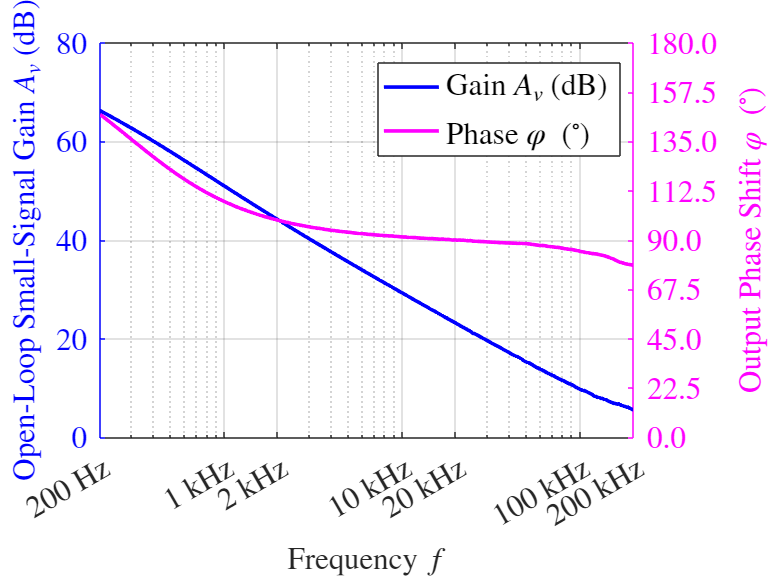

stc.axes.YTickLabel =  num2str(YTick', '%.1f');

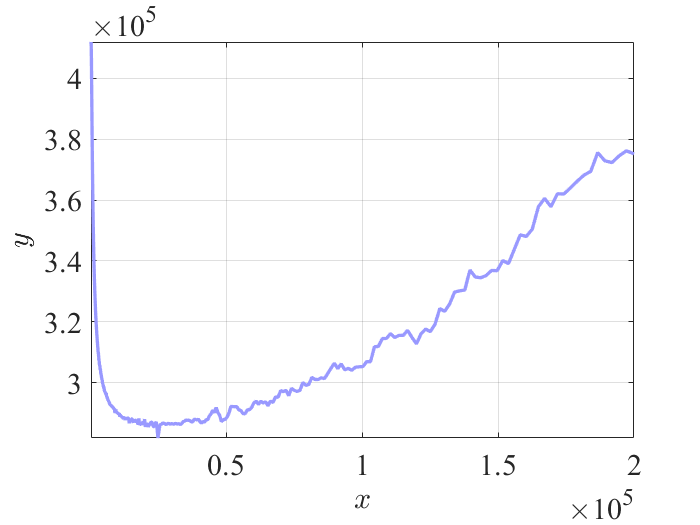

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]



MyPlot(f, A_v.*f)

% 运放测量板测量运放参数
R_7 = 3.9e3;
R_77 = 390e3;
R_6 = 3.9e3;
R_66 = 390e3;



TP1_Vos = 3.5334;  % V_IO
TP2_Vos = 13.579e-3;
TP1_Ib_R7 = 3.3392;
TP1_Ib_R6 = 3.6214;
TP1_DCGain = 4.797;
TP2_DCGain = -8.0405;
TP1_DCGain_2 = 3.9408;
TP2_DCGain_2 = -3.9738;
TP1_PSRR = 3.3278;
Delta_Vs = 2*(16 - 12);


I_B_neg = -(TP1_Ib_R7 - TP1_Vos)/(R_7*1001);
I_B_neg_2 = -(3.4266 - 3.5654)/(R_7*1001);
I_B_pos = (TP1_Ib_R6 - TP1_Vos)/(R_6*1001);
I_B_pos_2 = (3.72 - 3.5566)/(R_6*1001);
A_v_dc = abs( 1001 * (TP2_DCGain - TP2_Vos) / (TP1_DCGain - TP1_Vos));
A_v_dc_2 = abs( 1001 * (TP2_DCGain_2 - TP2_Vos) / (TP1_DCGain_2 - TP1_Vos));
PSRR_dc = abs( 1001 * Delta_Vs / (TP1_PSRR - TP1_Vos) );


disp(['V_IO = ', num2str(TP1_Vos/1001 * 1000), ' mV'])
disp(['I_B_neg = ', num2str(I_B_neg*10^9), ' nA'])
disp(['I_B_neg_2 = ', num2str(I_B_neg_2*10^9), ' nA'])
disp(['I_B_pos = ', num2str(I_B_pos*10^9), ' nA'])
disp(['I_B_pos_2 = ', num2str(I_B_pos_2*10^9), ' nA'])
I_B = 0.5*(I_B_pos_2 + I_B_neg_2)*10^9
I_OS = 0.5*(I_B_pos_2 - I_B_neg_2)*10^9

disp(['DC Gain 1 = ', num2str(A_v_dc), ' = ', num2str(20*log(A_v_dc)/log(10)), ' dB'])
A_v_dc_2
disp(['DC Gain 2 = ', num2str(A_v_dc_2), ' = ', num2str(20*log(A_v_dc_2)/log(10)), ' dB'])
disp(['DC PSRR = ', num2str(PSRR_dc), ' = ', num2str(20*log(PSRR_dc)/log(10)), ' dB'])

GBWP = 2.051e3* 199.4;
disp(['GBWP = ', num2str(GBWP/10^6), ' MHz'])
